# Calculate Bicycle-Rider Weight Distribution

Author: Ross Wilkinson

University: University of Colorado Boulder

This LiveScript compares CoM position and weight distribution between a kinematic estimate from Vantage data and a kinetic estimate using a force plate under the front wheel.

## Free-Body Diagram

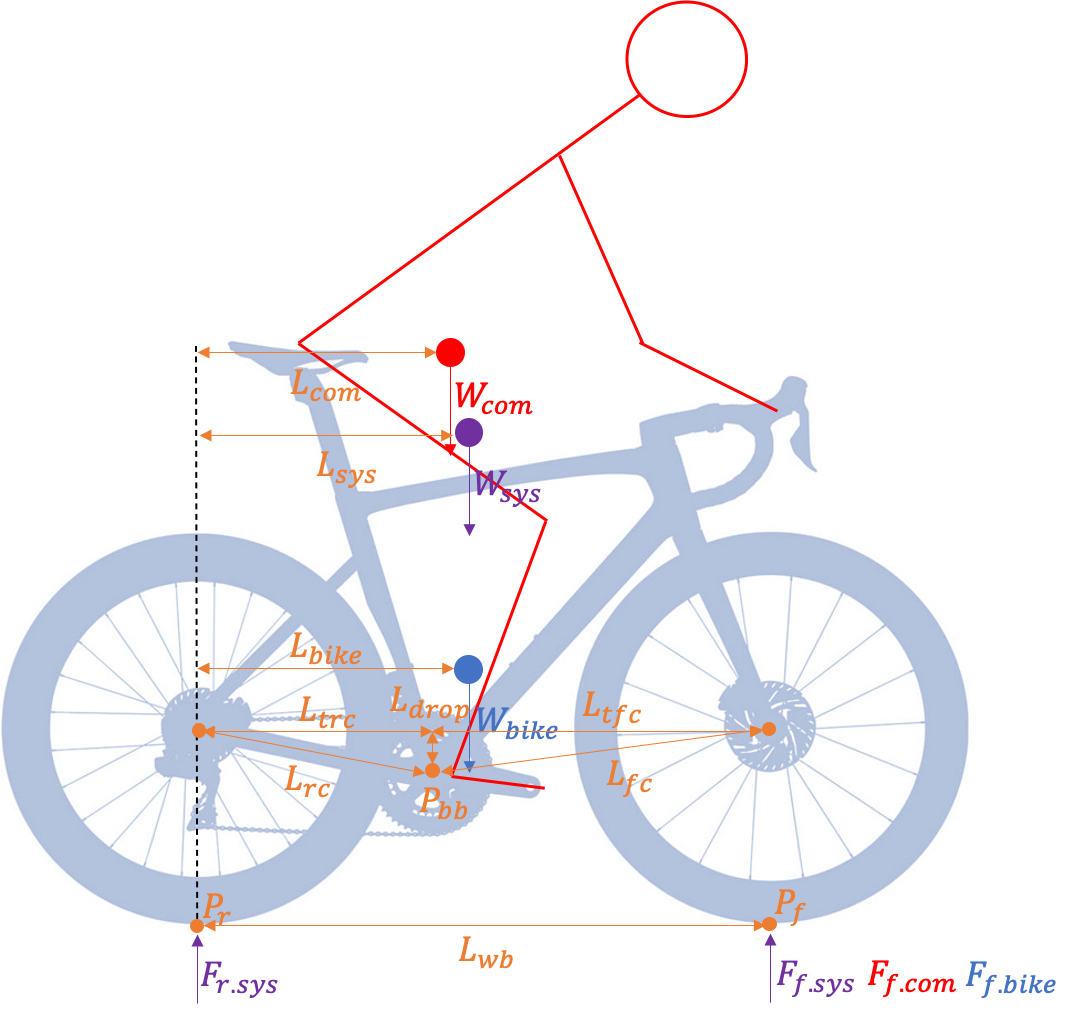

## Protocol

- Measure weight of rider

- Measure weight of rider and bicycle

- Measure force under front wheel of just the bicycle in the trainer

- Measure force under front wheel during cycling trial

- REMEMBER: Zero force plate before each measurement!

## Initialize workspace

clear;clc;close all

## Input bicycle geometry variables

- Bicycle: Tarmac SL7 56cm

- Source: [https://www.specialized.com/us/en/s-works-tarmac-sl7---dura-ace-di2/p/175292?color=290848-175292&searchText=94920-0044](https://www.specialized.com/us/en/s-works-tarmac-sl7---dura-ace-di2/p/175292?color=290848-175292&searchText=94920-0044)

- Units: Length (mm), Force/Weight (N)

Input bottom bracket drop (mm)

L_drop = 72;

Input front center (mm)

L_fc = 592;

Input rear center (mm)

L_rc = 410;

Calculate true front and rear center distances (mm)

L_tfc = L_fc * cos(asin(L_drop / L_fc));
L_trc = L_rc * cos(asin(L_drop / L_rc));

Calculate total wheelbase length (mm)

L_wb = L_tfc + L_trc;

## Calculate CoM based on front wheel force

**Input measured weights and forces**

Input the weight of the rider wearing all cycling gear (N).

W_com = 871.85;

Input the weight of the rider plus bicycle without rear wheel (N).

W_sys = 923.63;

Input the measured force under the front wheel with only the bike in wahoo trainer with loose rear axle (N).

F_f_bike = 37.52;

Input the average measured force under the front wheel during the cycling trial (N).

F_f_sys = 392.88;

**Calculations**

Calculate bicycle weight as total weight minus rider weight (N).

W_bike = W_sys - W_com;

Calculate force under front wheel due to the rider (N).

F_f_com = F_f_sys - F_f_bike;

Calculate the system's, rider's, and bike's CoM position relative to the rear axle by dividing the total torque around the rear axle due to the rider by the respective weights.

L_sys = (F_f_sys * L_wb) / W_sys;
L_com = (F_f_com * L_wb) / W_com;
L_bike = (F_f_bike * L_wb) / W_bike;

Calculate the system's, rider's, and bike's CoM position relative to the bottom bracket by subtracting the CoM position from the true rear center distance.

L_sys2bb = L_trc - L_sys;
L_com2bb = L_trc - L_com;
L_bike2bb = L_trc - L_bike;

Calculate WDF

WDF_fp = F_f_sys / W_sys * 100;

## Print results

**CoM Results**

Print the position of the rider, system, and bike CoM relative to the rear axle and to the bottom bracket.

fprintf('Force-plate: \n')

Force-plate: 


fprintf('The measured front-wheel force was %4.1f N\n',F_f_sys)

The measured front-wheel force was 408.0 N


if L_sys2bb < 0
    fprintf('The system''s CoM is %4.1f mm in front of the bottom bracket\n', abs(L_sys2bb))
else
    fprintf('The system''s CoM is %4.1f mm behind the bottom bracket\n', abs(L_sys2bb))
end

The system's CoM is 34.2 mm in front of the bottom bracket



if L_com2bb < 0
    fprintf('The rider''s CoM is %4.1f mm in front of the bottom bracket\n', abs(L_com2bb))
else
    fprintf('The rider''s CoM is %4.1f mm behind the bottom bracket\n', abs(L_com2bb))
end

The rider's CoM is 17.6 mm in front of the bottom bracket



if L_bike2bb < 0
    fprintf('The bike''s CoM is %4.1f mm in front of the bottom bracket\n', abs(L_bike2bb))
else
    fprintf('The bike''s CoM is %4.1f mm behind the bottom bracket\n', abs(L_bike2bb))
end

The bike's CoM is 314.6 mm in front of the bottom bracket


**WDF Results**

fprintf('WDF as measured by the force plate is %4.1f%%\n', WDF_fp)

WDF as measured by the force plate is 44.2%


## Calculate WDF based on Vantage CoM estimate

Load Vantage CoM results

[file, path] = uigetfile();
data = load([path file]);
L_com2bb_ = data.com2bbMean;

**Calculate WDF using CoM to BB distance**

Calculate CoM results

L_com_ = L_trc - L_com2bb_;


Vantage-CoM estimates: 


F_f_com_ = (W_com * L_com_) / L_wb;

The estimated front-wheel force was 423.5 N


F_f_sys_ = F_f_com_ + F_f_bike;
L_sys_ = (F_f_sys_ * L_wb) / W_sys;

The system's CoM is 50.9 mm in front of the bottom bracket


Calculate the system's CoM position relative to the bottom bracket by subtracting the CoM position from the true rear center distance.

L_sys2bb_ = L_trc - L_sys_;

The rider's CoM is 35.2 mm in front of the bottom bracket


Calculate WDF

WDF_van = F_f_sys_ / W_sys * 100;

WDF as estimated by the Vantage data is 45.9%


## Print results

**CoM Results**

Print the position of the rider, system, and bike CoM relative to the rear axle and to the bottom bracket.

fprintf('\nVantage-CoM estimates: \n')
fprintf('The estimated front-wheel force is %4.1f N\n',F_f_sys_)
if L_sys2bb_ < 0
    fprintf('The system''s CoM is %4.1f mm in front of the bottom bracket\n', abs(L_sys2bb_))
else
    fprintf('The system''s CoM is %4.1f mm behind the bottom bracket\n', abs(L_sys2bb_))
end

if L_com2bb_ < 0
    fprintf('The rider''s CoM is %4.1f mm in front of the bottom bracket\n', abs(L_com2bb_))
else
    fprintf('The rider''s CoM is %4.1f mm behind the bottom bracket\n', abs(L_com2bb_))
end

**WDF Results**

fprintf('WDF as estimated by the Vantage data is %4.1f%%\n', WDF_van)